Loading In Rosbag

bagSelect = rosbag('2022-07-14-22-17-15.bag');

Parse Voltage and Current Data

voltageLog = select(bagSelect, 'Topic', '/amr/status/voltage')

voltageLog =   BagSelection with properties:

           FilePath: 'C:\Users\johni\github\Thesis-\Sensor Logging\2022-07-14-22-17-15.bag'
          StartTime: 1.6578e+09
            EndTime: 1.6578e+09
        NumMessages: 143
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [143×4 table]


currentLog = select(bagSelect, 'Topic', '/amr/status/current')

currentLog =   BagSelection with properties:

           FilePath: 'C:\Users\johni\github\Thesis-\Sensor Logging\2022-07-14-22-17-15.bag'
          StartTime: 1.6578e+09
            EndTime: 1.6578e+09
        NumMessages: 143
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [143×4 table]


Plot Voltage Data

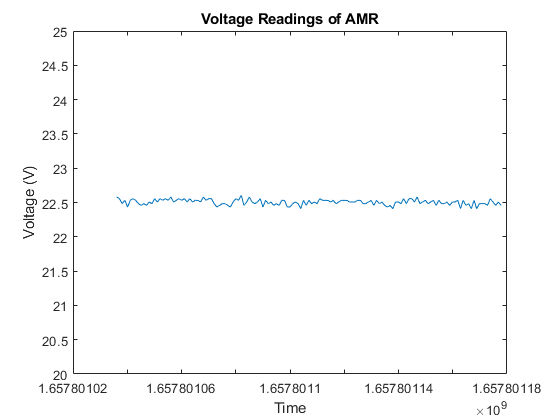

voltagePlot = timeseries(voltageLog);
plot(voltagePlot);
title('Voltage Readings of AMR');
xlabel('Time');
ylabel('Voltage (V)');
ylim([20 25]);

Plot Current Data

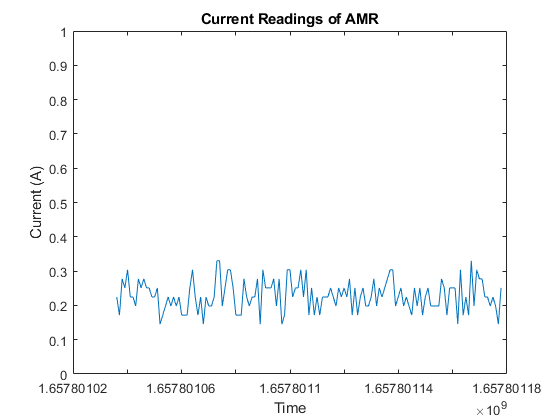

currentPlot = timeseries(currentLog);
plot(currentPlot);
title('Current Readings of AMR');
xlabel('Time');
ylabel('Current (A)');
ylim([0 1]);